# A Rough Estimation Contour for S_EI and S_IE

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/zx555/Documents/MATLAB/NYU-Vision-main/MFModel Code'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])

N_HC = 3; 
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons; 
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC; 
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6; 

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I
% sparse metrices containing 0 or 1. 
% Row_i Column_j means neuron j projects to neuron i
% add periodic boundary
C_EE = ConnectionMat(N_E,NnE,Size_E,...
                     N_E,NnE,Size_E,...
                     Peak_EE,SD_E,Dist_LB,1);

Elapsed time is 11.970954 seconds.



C_EI = ConnectionMat(N_E,NnE,Size_E,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,0);

Elapsed time is 4.630282 seconds.



C_IE = ConnectionMat(N_I,NnI,Size_I,...
                     N_E,NnE,Size_E,...
                     Peak_I,SD_E,Dist_LB,0);

Elapsed time is 4.192463 seconds.



C_II = ConnectionMat(N_I,NnI,Size_I,...
                     N_I,NnI,Size_I,...
                     Peak_I,SD_I,Dist_LB,1);

Elapsed time is 1.540038 seconds.


## Variables and Parameters

%RefTimeE = zeros(N_E,1); VE = 0.5*rand(N_E,1)-0.5; SpE = sparse(N_E,1); GE_ampa_R = zeros(N_E,1); GE_nmda_R = zeros(N_E,1); GE_gaba_R = zeros(N_E,1); GE_ampa_D = zeros(N_E,1); GE_nmda_D = zeros(N_E,1); GE_gaba_D = zeros(N_E,1);
%RefTimeI = zeros(N_I,1); VI = 1.5*rand(N_I,1)-0.5; SpI = sparse(N_I,1); GI_ampa_R = zeros(N_I,1); GI_nmda_R = zeros(N_I,1); GI_gaba_R = zeros(N_I,1); GI_ampa_D = zeros(N_I,1); GI_nmda_D = zeros(N_I,1); GI_gaba_D = zeros(N_I,1); 
load('Initials.mat')
%parameters
S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.033; S_EI = 0.061; S_IE = 0.0087; S_II = 0.048;
%S_EE = 0.029; S_EI = 0.055; S_IE = 0.0081; S_II = 0.048; %Tuned
%S_EE = 0.028; S_EI = 0.056; S_IE = 0.0095; S_II = 0.042; % original
p_EEFail = 0.2; S_amb = 0.01;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms
dt = 0.2;
gL_E = 1/20;  Ve = 14/3; S_Elgn = 0.059; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; S_Ilgn = 0.084; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 
rE_amb = 0.72; rI_amb = 0.36;

% Replace S_EI by testing values
GridNum = 25;
S_EI_Mtp = [0.4, 4];
S_IE_Mtp = [0.12,0.48];
S_EItest = linspace(S_EI_Mtp(1),S_EI_Mtp(2),GridNum+1)*S_EE;
S_IEtest = linspace(S_IE_Mtp(1),S_IE_Mtp(2),GridNum+1)*S_EE;

## MF estimation: 

cluster = parcluster('local');

SBound = 3.2; % multipliers of S_EE

Fr_NoFix = zeros(2,length(S_EItest),length(S_IEtest));
mV_NoFix = zeros(2,length(S_EItest),length(S_IEtest));
Fr_NoFixVar = zeros(2,length(S_EItest),length(S_IEtest));
mV_NoFixVar = zeros(2,length(S_EItest),length(S_IEtest));
Fr_NoFixTraj = cell(length(S_EItest),length(S_IEtest));
mV_NoFixTraj = cell(length(S_EItest),length(S_IEtest));

loopCount = zeros(length(S_EItest),length(S_IEtest)); % count the number of loops
ConvIndi = logical(loopCount);

SampleNum = 200;
StopNum = 300;
aa = floor(length(S_IEtest)); % Matlab always fail to directly see this as a whole number!!!
tic
for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    parfor S_IEInd = 1:aa
    S_IE = S_IEtest(S_IEInd);
    
    if S_IE*10+S_EI<(SBound+0.01)*S_EE
        disp(['S_IE = ' num2str(S_IE) ', S_EI = ' num2str(S_EI) '; break...'])
        continue
    end
    
    tic
    [Fr_NoFixTraj{S_EIInd,S_IEInd},mV_NoFixTraj{S_EIInd,S_IEInd},...
     loopCount(S_EIInd,S_IEInd),   ConvIndi(S_EIInd,S_IEInd)    ]...
                  = MeanFieldEst_BkGd_Indep(C_EE,C_EI,C_IE,C_II,...
                                            S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                            lambda_E,S_Elgn,rE_amb,S_amb,...
                                            lambda_I,S_Ilgn,rI_amb,...
                                            tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,...
                                            rhoE_ampa,rhoE_nmda,rhoI_ampa,rhoI_nmda,...
                                            gL_E,gL_I,Ve,Vi,...
                                            N_HC,n_E_HC,n_I_HC,'End',SampleNum,StopNum);
                                        
    toc    
    end
end

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).
S_IE = 0.0044352, S_EI = 0.0132; break...
S_IE = 0.00396, S_EI = 0.0132; break...
S_IE = 0.0072864, S_EI = 0.0132; break...
S_IE = 0.0068112, S_EI = 0.0132; break...
S_IE = 0.0082368, S_EI = 0.0132; break...
S_IE = 0.0077616, S_EI = 0.0132; break...
S_IE = 0.0049104, S_EI = 0.0132; break...
S_IE = 0.0091872, S_EI = 0.0132; break...
S_IE = 0.008712, S_EI = 0.0132; break...
S_IE = 0.0053856, S_EI = 0.0132; break...
S_IE = 0.0058608, S_EI = 0.0132; break...
S_IE = 0.006336, S_EI = 0.0132; break...
Firing rates unconverged
Elapsed time is 6.580103 seconds.
Firing rates unconverged
Firing rates unconverged
Firing rates unconverged
Firing rates unconverged
Elapsed time is 6.794433 seconds.
Firing rates unconverged
Elapsed time is 6.929162 seconds.
Firing rates unconverged
Elapsed time is 4.978676 seconds.
Elapsed time is 6.176817 seconds.
Firing rates unconverged
Elapsed time

toc

Elapsed time is 797.738481 seconds.



for S_EIInd = 1:length(S_EItest)
    S_EI = S_EItest(S_EIInd);
    for S_IEInd = 1:length(S_IEtest)
        S_IE = S_IEtest(S_IEInd);
    if S_IE*10+S_EI<(SBound+0.01)*S_EE
        disp(['S_IE = ' num2str(S_IE) ', S_EI = ' num2str(S_EI) '; break...'])
        continue
    end
        
    Fr_NoFix(:,S_EIInd,S_IEInd) = mean(Fr_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    mV_NoFix(:,S_EIInd,S_IEInd) = mean(mV_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),2);
    Fr_NoFixVar(:,S_EIInd,S_IEInd) = var(Fr_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    mV_NoFixVar(:,S_EIInd,S_IEInd) = var(mV_NoFixTraj{S_EIInd,S_IEInd}(:,end-SampleNum:end),0,2);
    end
end

S_IE = 0.00396, S_EI = 0.0132; break...
S_IE = 0.0044352, S_EI = 0.0132; break...
S_IE = 0.0049104, S_EI = 0.0132; break...
S_IE = 0.0053856, S_EI = 0.0132; break...
S_IE = 0.0058608, S_EI = 0.0132; break...
S_IE = 0.006336, S_EI = 0.0132; break...
S_IE = 0.0068112, S_EI = 0.0132; break...
S_IE = 0.0072864, S_EI = 0.0132; break...
S_IE = 0.0077616, S_EI = 0.0132; break...
S_IE = 0.0082368, S_EI = 0.0132; break...
S_IE = 0.008712, S_EI = 0.0132; break...
S_IE = 0.0091872, S_EI = 0.0132; break...
S_IE = 0.00396, S_EI = 0.017952; break...
S_IE = 0.0044352, S_EI = 0.017952; break...
S_IE = 0.0049104, S_EI = 0.017952; break...
S_IE = 0.0053856, S_EI = 0.017952; break...
S_IE = 0.0058608, S_EI = 0.017952; break...
S_IE = 0.006336, S_EI = 0.017952; break...
S_IE = 0.0068112, S_EI = 0.017952; break...
S_IE = 0.0072864, S_EI = 0.017952; break...
S_IE = 0.0077616, S_EI = 0.017952; break...
S_IE = 0.0082368, S_EI = 0.017952; break...
S_IE = 0.008712, S_EI = 0.017952; break...
S_IE = 0.00396, S_EI

## Contour maps

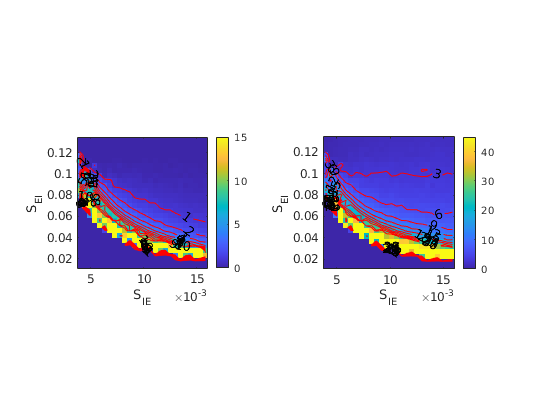

Fr_Plot = Fr_NoFix;
S_IEBound = 8e-3;
DeleteInd = false(size(Fr_Plot));
DeleteInd(:,:,S_IEtest<S_IEBound) = true;
Fr_Plot(Fr_NoFix <=eps & DeleteInd) = nan;

figure('Name','Rough Countour S_EI S_IE')
subplot 121
imagesc(S_IEtest,S_EItest,squeeze(Fr_Plot(1,:,:)))
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')
colorbar
caxis([0 15])
axis square
hold on
[C1,h1]= contour(S_IEtest,S_EItest,squeeze(Fr_Plot(1,:,:)),1:1:10,'ShowText','on','color','r');
clabel(C1,h1,'FontSize',10,'Color','k')
axis square
hold off
%axis([min(S_EItest) max(S_EItest) min(S_IEtest) max(S_IEtest)])

subplot 122
imagesc(S_IEtest,S_EItest,squeeze(Fr_Plot(2,:,:)))
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')
colorbar
caxis([0 45])
axis square
hold on
[C2,h2]= contour(S_IEtest,S_EItest,squeeze(Fr_Plot(2,:,:)),3:3:30,'ShowText','on','color','r');
clabel(C2,h2,'FontSize',10,'Color','k')
axis square
hold off

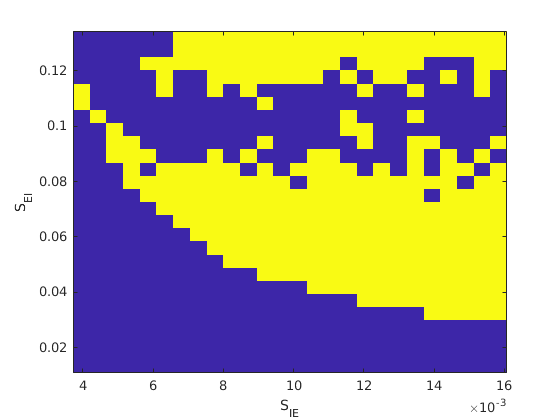

%axis([min(S_EItest) max(S_EItest) min(S_IEtest) max(S_IEtest)])

figure('Name','Convergence')
imagesc(S_IEtest,S_EItest,ConvIndi)
xlabel('S_{IE}'); ylabel('S_{EI}');
set(gca,'YDir','Normal')

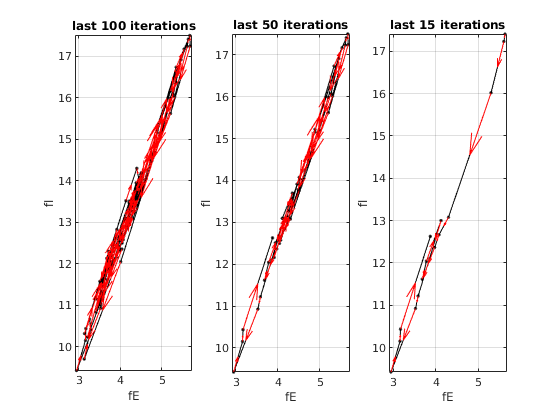

figure('Name','Trajectories-Last')
subplot 131
plot_dir(Fr_NoFixTraj{9,13}(1,end-100:end)',Fr_NoFixTraj{9,13}(2,end-100:end)');
xlabel('fE');ylabel('fI')

title('last 100 iterations')

subplot 132
plot_dir(Fr_NoFixTraj{9,13}(1,end-50:end)',Fr_NoFixTraj{9,13}(2,end-50:end)');
xlabel('fE');ylabel('fI')

title('last 50 iterations')

subplot 133
plot_dir(Fr_NoFixTraj{9,13}(1,end-15:end)',Fr_NoFixTraj{9,13}(2,end-15:end)');
xlabel('fE');ylabel('fI')

title('last 15 iterations')

## Sanity check by network simulations

S_EE = 0.033, S_EI = 0.074976, S_IE = 0.0068112, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

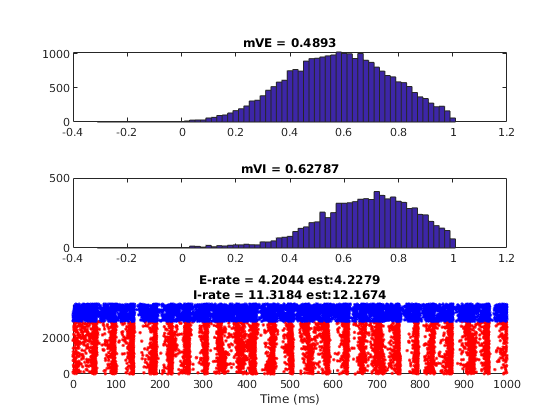

S_EE = 0.033, S_EI = 0.074976, S_IE = 0.0068112, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.046464, S_IE = 0.010138, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.046464, S_IE = 0.010138, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

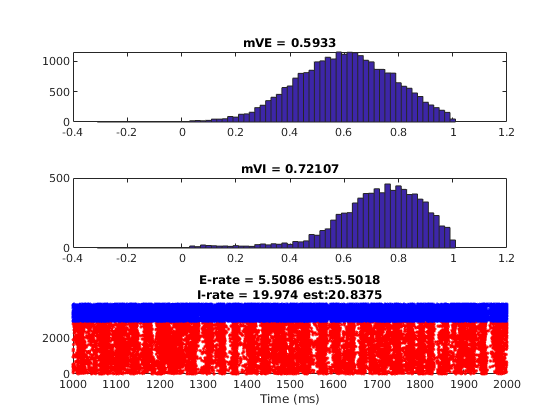

S_EE = 0.033, S_EI = 0.041712, S_IE = 0.013939, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

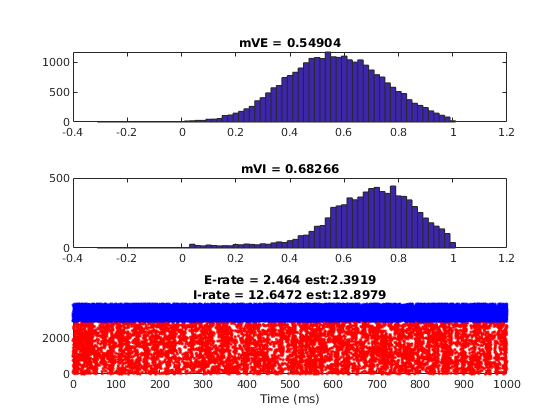

S_EE = 0.033, S_EI = 0.041712, S_IE = 0.013939, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

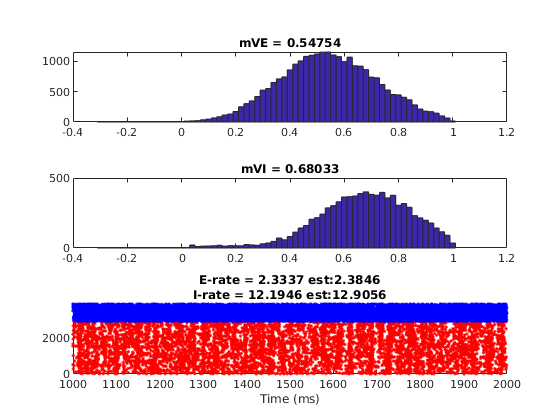

S_EE = 0.033, S_EI = 0.06072, S_IE = 0.008712, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.06072, S_IE = 0.008712, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

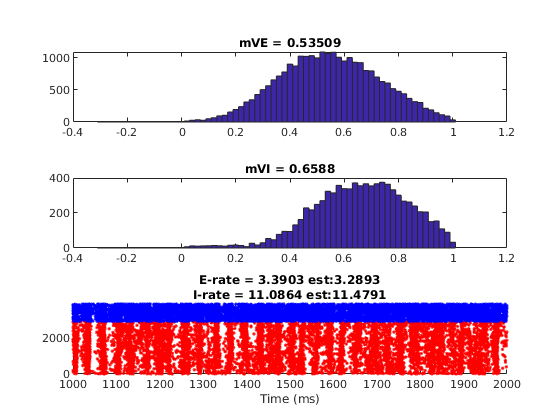

S_EE = 0.033, S_EI = 0.074976, S_IE = 0.0072864, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.074976, S_IE = 0.0072864, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.093984, S_IE = 0.0049104, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EE = 0.033, S_EI = 0.093984, S_IE = 0.0049104, S_II = 0.048
S_Elgn = 0.059, lambda_E = 0.08, S_Ilgn = 0.084, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.72, rI_amb = 0.36

S_EIInd_check = [14,8,7,11,14,18];
S_IEInd_check = [7 14 22 11 8 3];
Fr_Check = zeros(2,length(S_EIInd_check));
T = 2000; sampleT = 2; SimulationT = 1000;

E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
    
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2)); 
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

for CheckInd = 1:length(S_EIInd_check)
    S_EI = S_EItest(S_EIInd_check(CheckInd));
    S_IE = S_IEtest(S_IEInd_check(CheckInd));
    load('Initials.mat')
    %E_SpHis= []; I_SpHis=[];
    E_Sp = []; I_Sp = [];
    VE_T = []; VI_T = [];
    sampleN = floor(sampleT/dt); % sample each 2 ms
    SimulationN = floor(SimulationT/dt); % show and check every 200ms
    for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,...
          oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
     oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
          oGI_ampa_D,oGI_nmda_D,oGI_gaba_D] = ...
          V1NetworkUpdate(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,...
                                          GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                          RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                          GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                          C_EE,C_EI,C_IE,C_II,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
                          S_amb,lambda_E,lambda_I,rE_amb,rI_amb);
                      
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
                                              GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
                                              GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;

% When reaching every 200ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>500
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
                         ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
                         'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
                         ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
                         'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
    
    fprintf(ParameterDisp)
    h = figure(1);
    subplot 311
    hist(oVE,-0.3:0.02:1)
    title(['mVE = ' num2str(nanmean(VE_T))])
    %E_SpHis = [E_SpHis,sum(oSpE)];
    %axis([-0.4 1.1 0 6000])
    
    subplot 312
    hist(oVI,-0.3:0.02:1)
    title(['mVI = ' num2str(nanmean(VI_T))])
    %I_SpHis = [I_SpHis,sum(oSpI)];
    %axis([-0.4 1.1 0 2000])
    
    

    %E_Ind = 10000:13000; I_Ind = 3300:4300;
    scatterE = find(ismember(E_Sp(:,1),E_Ind));
    scatterI = find(ismember(I_Sp(:,1),I_Ind));
    [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
    [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);

    WinSize = SimulationT;
    T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
    E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
    I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
    E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
    I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);

    f_EnIOneStep = MeanFieldEst_BkGd(N_EE,N_EI,N_IE,N_II,...
                                     S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                     lambda_E,S_Elgn,rE_amb,S_amb,...
                                     lambda_I,S_Ilgn,rI_amb,...
                                     gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));

    subplot 313
    hold on
    scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
    scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
    title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
    xlabel('Time (ms)')
    xlim(T_RateWindow)
    ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
    drawnow
    %pause
    close(h)
    end

    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
%     if sum(isnan(oVE))>0.6*N_E
%         error('warning!: Network exploded')
%     end
    end
    Fr_Check(:,CheckInd) = [E_Rate;I_Rate];
end



for CheckInd = 1:length(S_EIInd_check)
    Fr_NoFixCheck(:,CheckInd) = squeeze(Fr_NoFix(:,S_EIInd_check(CheckInd),S_IEInd_check(CheckInd)))
        
end